clear
m = 1; %[kg]
H = tf(1,[m 0 0])

H =
 
   1
  ---
  s^2
 
Continuous-time transfer function.
Model Properties


wc = 10 %[Hz} crossover frequency

wc = 10

P = abs(m*wc^2/(1 + i))

P = 70.7107

D = P/wc

D = 7.0711

C = tf([D P],1)

C =
 
  7.071 s + 70.71
 
Continuous-time transfer function.
Model Properties


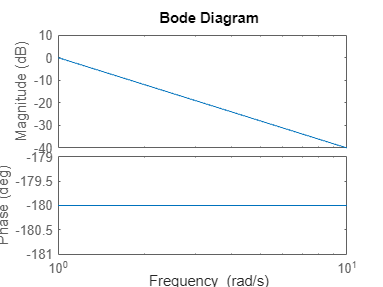

bode(H)

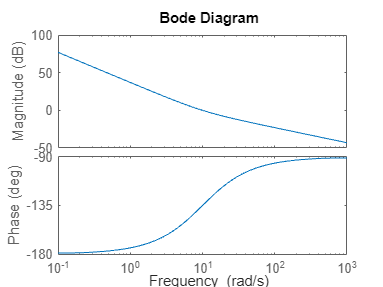

bode(H*C)